% clear;
data = load('resultadosCSV_magic.txt');

stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

tau_stop    = 15.72e-12;
n_min_stop  = 35;
n_max_stop  = 353;
tau_start   = 16.23e-12;
n_min_start = 27

n_min_start = 27

n_max_start = 335

n_max_start = 335

T           = 5e-9;

T_buscado = 1/(2*5e6)

T_buscado = 1.0000e-07

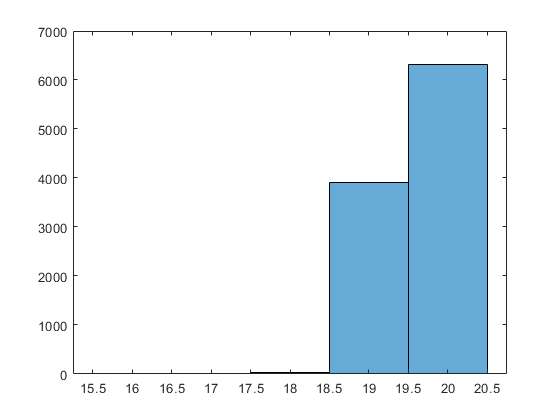

t_fino = (start-stop)*tau_stop;

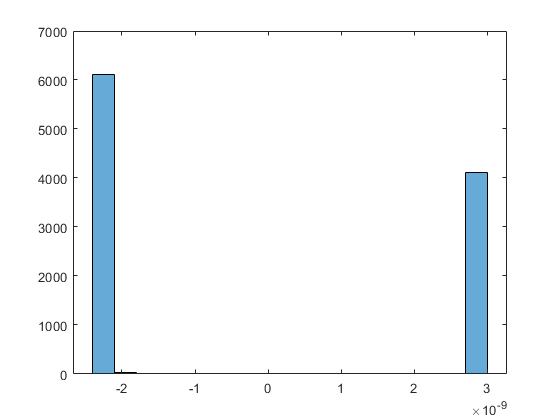

histogram(t_fino)

histogram(coarse)

st = start-stop;
indices_st = find(st>0);
indices_st_neg = find(st<0);
st(indices_st_neg) = st(indices_st_neg) + (n_max_start-n_min_start);
st_positivo = st(indices_st);
std(st_positivo)

ans = 2.1303

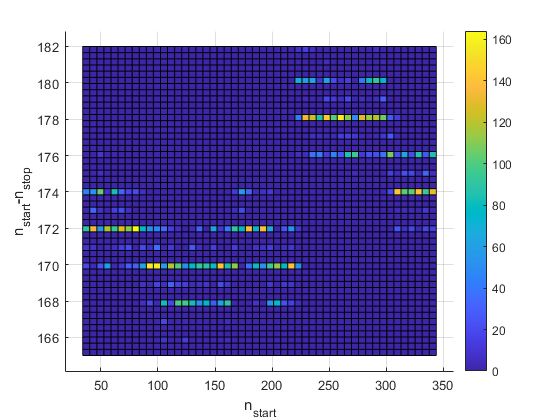

hist3([start, st], 'CdataMode','auto', 'Nbins',[50 50])
view(2); colorbar; ylabel('n_{start}-n_{stop}'); xlabel('n_{start}')
exportgraphics(gcf,'start-stop_magic.eps');